# Linear Systems Applications

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

## Linear regression

Linear regression is a staple in traditional fields (physics and chemistry) and newer disciplines (machine learning and data science). This section will derive the least-squares solution to the linear regression problem.

**Data**

Suppose that you want to estimate a linear relationship for the random data shown below.

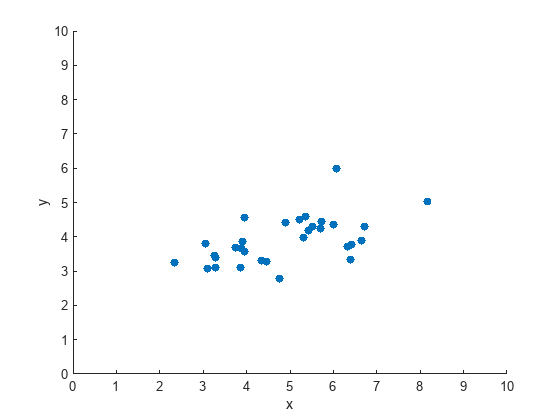

n = 31;
 

x = sort(normrnd(5,1.75,n,1));
y = 1*normrnd(2,0.6,n,1) + x*(0.2+rand(1,1)/2);

scatter(x,y,"filled")
xlabel("x")
ylabel("y")
axis([0 10 0 10])

  **Try.** Generate the data by running this section.

**Residual**

 The relationship between $x$ and $y$ can be approximated by a linear function:

    
$$f(x) = w_0 + w_1 x$$


 Typically, the best fit line is chosen to be the one that minimizes the sum of squares error. This error is called the residual.

    
$$R(w_0,w_1) = \sum_i [ y_i - (w_0 + w_1 x_i) ]^2$$


Visually, the residual is computed by summing the squares of the vertical differences from the line.

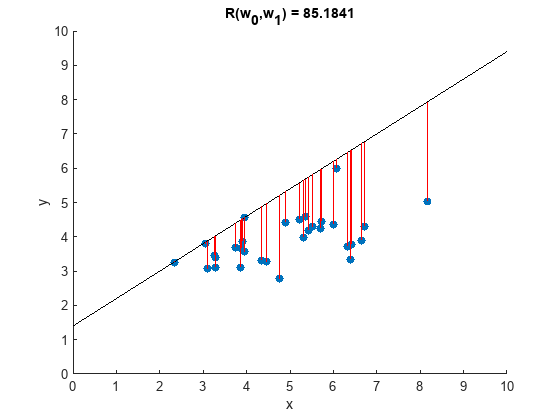

w0 = 1.4;
w1 = 0.8;
 

f = @(x) w0 + w1*x;
R = sum( (y - f(x)).^2 );

scatter(x,y,"filled")
hold on
plot([0 12],f([0 12]),"k-")
plot([x x]',[f(x) y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
axis([0 10 0 10])

  **Try.** Adjust the parameters of the linear function to reduce the sum of square error.

**Writing the linear approximation in matrix form **

To find the parameters $w_1$ and $w_2$ that minimize the residual $R$, you can solve for the least-squares solution.

To set up this system, write the data ($x_i$ and $y_i$) in terms of vectors:

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$   and   $\mathbf{y} = \left( \matrix{ y_1 \cr y_2 \cr \vdots \cr y_n } \right)$

Then write a linear approximation vector $\tilde{\mathbf{y}} = w_0 + w_1 \mathbf{x}$ as a linear combination:

     $\tilde{\mathbf{y}} = w_0 \left( \matrix{ 1 \cr 1 \cr \vdots \cr 1} \right)
+ w_1 \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$    which is equivalent to the matrix form:     $\tilde{\mathbf{y}} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) \left( \matrix{ w_0 \cr w_1 } \right)
$.

This can be written as

    
$$\tilde\mathbf{y} = \mathbf{Xw}$$


where

    $\mathbf{X} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) $ and vector $\mathbf{w} = \left( \matrix{ w_0 \cr w_1 } \right)$.

** Exercise**. In this exercise, you will write the approximate solution $\tilde\mathbf{y} $ for the example illustrated above in matrix form using MATLAB.

1. Define the matrix $\mathbf{X}$ by concatenating the column of ones contained in the variable `u` with the vector `x `(which stores the data's $x$-locations). You can [concatenate](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html#OverviewCreatingAndConcatenatingExample-3) two column vectors `a` and `b` using the syntax: `[a b]`.

u = ones(n,1); % A vector of ones
% Define X:


2. Define the vector $\mathbf{w}$ using the variables `w0` and `w1`.

3. Compute the linearly approximated y-values: $\tilde\mathbf{y} = \mathbf{Xw}$. Assign $\tilde{\mathbf{y}$ to the MATLAB variable `y_approx`.

**Visualize the linear approximations of the data**

  **Try.** Run this section to visualize the estimates stored in `y_approx`.

 
try  
    fls = @(x) w(1) + w(2)*x;
    R = sum( (y - fls(x)).^2 );

    scatter(x,y,"filled")
    hold on
    scatter(x,y_approx,'s',"filled")
    plot([0 12],fls([0 12]),"k:")
    plot([x x]',[fls(x) y]',"r:")
    hold off
    title("R(w_0,w_1) = " + num2str(R))
    xlabel("x")
    ylabel("y")
    leg = legend('Data',"$\tilde{\mathbf{y}}$");
    set(leg,"interpreter","latex")
    axis([0 10 0 10])
    
    chi=get(gca, 'Children');
    set(gca, 'Children',flipud(chi));
catch ME
    warning("Plot failed because: "+ME.message)
end

**Solution to the least-squares problem **

**General solution**

In the linear regression problem, you want to minimize the sum of square errors. The calculus approach is shown here. The residuals can be written in terms of the matrix elements as

    
$$\begin{array}{rl}
R(w_0,w_1) &= \sum_i [ y_i - (w_0 + w_1 x_i) ]^2
\\
 &= \sum_i (y_i - \tilde{y}_i )^2
\\
 &= \sum_i \left(y_i -  \sum_j X_{ij} w_{j} \right)^2
\end{array}
$$


To minimize this equation with respect to $w_i$ using a calculus approach, find the stationary points. To do so, take the derivative $\frac{\partial}{\partial w_k}$ and set it equal to zero:

    
$$\begin{array}{rl}
\frac{\partial}{\partial w_k} R(w_0,w_1)  &= \sum_i 2\left( y_i - \sum_j X_{ij} w_{j} \right) \frac{\partial}{\partial w_k} \left(y_i - \sum_j  X_{ij} w_{j} \right)
\\
0 &= 2\sum_i  \left( y_i - \sum_j X_{ij} w_{j} \right) ( - X_{ik} )
\\
0 &= \sum_i  - y_i X_{ik} + \sum_{ij} X_{ij} w_{j} X_{ik} 
\end{array}
$$


You can write the final equation in matrix notation as:

    
$$\begin{array}{rl}
0 &= -\mathbf{y}^\top \mathbf{X} + \mathbf{X}^\top \mathbf{X}\mathbf{w} 
\\
\mathbf{X}^\top \mathbf{X}\mathbf{w} & = \mathbf{X}^\top \mathbf{y}
\end{array}$$


The solution to this system, $\mathbf{w}$, is a critical point of the residual function $R$. An additional argument (not shown here) is required to demonstrate that this minimizes the residual (this is intuitive due to the original quadratic form of the residual).

To solve this system for the coefficients $\mathbf{w}$, you can use any standard method for solving a matrix system. Compare this result to the standard form of a linear system in matrix form:

    
$$\mathbf{X}^\top \mathbf{X}\mathbf{w}  = \mathbf{X}^\top \mathbf{y}$$
 
$$\Leftrightarrow$$

$$\mathbf{Aw} = \mathbf{b}$$
 

These systems are equivalent with $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ and $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$.

** Exercise**. You can use the equation

    
$$\mathbf{X}^\top \mathbf{X}\mathbf{w}  = \mathbf{X}^\top \mathbf{y}$$


to find the least-squares solution of the linear regression problem. To do so, you can define the matrix $\mathbf{A}$ and right-hand side (RHS) vector $\mathbf{b}$ and then solve for the matrix solution. 

1. Compute the matrix `A` and RHS vector `b` using the formulas $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ and $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$.

**Hint**: Use an apostrophe (') to compute the [matrix transpose](https://www.mathworks.com/help/matlab/ref/ctranspose.html).

2. Compute matrix solution using the backslash operator. Save the result in `w`.

Note: you don't have to define `A` and `b` to compute the solution. You can use their expressions directly.

**Visualize the least-squares fit**

  **Try.** Once your solution is complete (i.e., you have solved for $\mathbf{w}$), you can view the least-squares solution by running this section.

 
try
    fls = @(x) w(1) + w(2)*x;
    R = sum( (y - fls(x)).^2 );
    scatter(x,y,"filled")
    hold on
    plot([0 12],fls([0 12]),"k-")
    plot([x x]',[fls(x) y]',"r")
    hold off
    
    title("R(w_0,w_1) = " + num2str(R))
    xlabel("x")
    ylabel("y")
    axis([0 10 0 10])
catch ME
    warning("Plot failed because: "+ME.message)
end

- How close was your by-hand fit residual to the least-squares fit residual?

## Linear circuits

Simple linear circuits can be analyzed using Kirchhoff's circuit laws. Matrices provide a natural framework: they can concisely capture the many linear equations that model the circuit network. In this section, you will derive the matrix form of the linear equations that represent a linear circuit and solve for the currents in that circuit.

**Kirchhoff's current law**

The sum of all currents flowing into a node equals the sum of currents flowing out of the node.

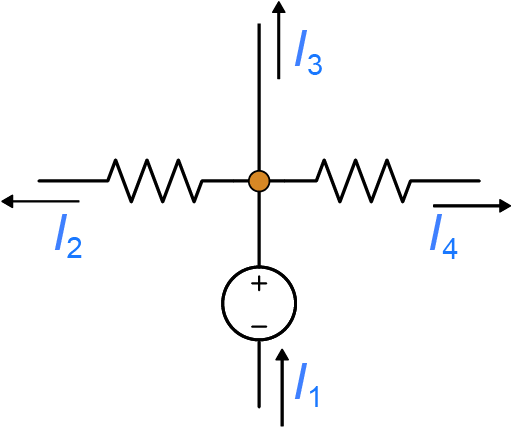

*At this node, Kirchhoff's current law implies *$I_1 = I_2 + I_3 + I_4 $

**Kirchhoff's voltage law**

The sum of voltages around a closed-loop of a circuit is zero. Mathematically:

    
$$\sum_{k} V_k = 0$$


where $V_k$ is the potential difference across the $k^{th}$ branch of the circuit. Applying Ohm's law gives the potential drop across each resistor: $V = IR$.

 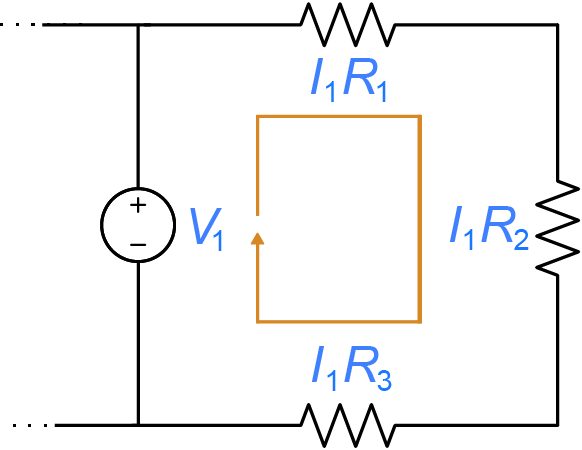

*The potential drop across the resistors in this closed loop must equal the potential generated by the voltage source: *$V_1 - I_1 R_1 - I_1 R_2 - I_1 R_3 = 0$

**Matrix representation of a circuit**

In this section, the pictured linear circuit will be analyzed using Kirchhoff's laws, written in matrix form.

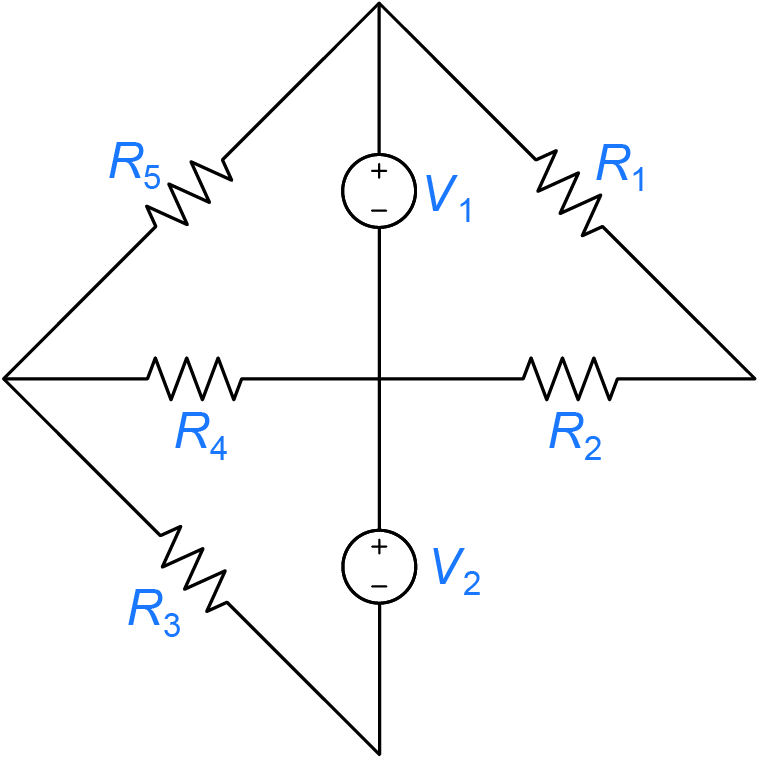

*The circuit to be analyzed*

**Derivation of the equations**

Before writing the equations, it is useful to define current paths through the circuit. This provides a framework for applying Kirchhoff's laws. Note that the current paths are arbitrary, as current flowing in the opposite direction is represented by a negative value. The chosen reference directions are necessary to determine the correct form of Kirchhoff's laws.

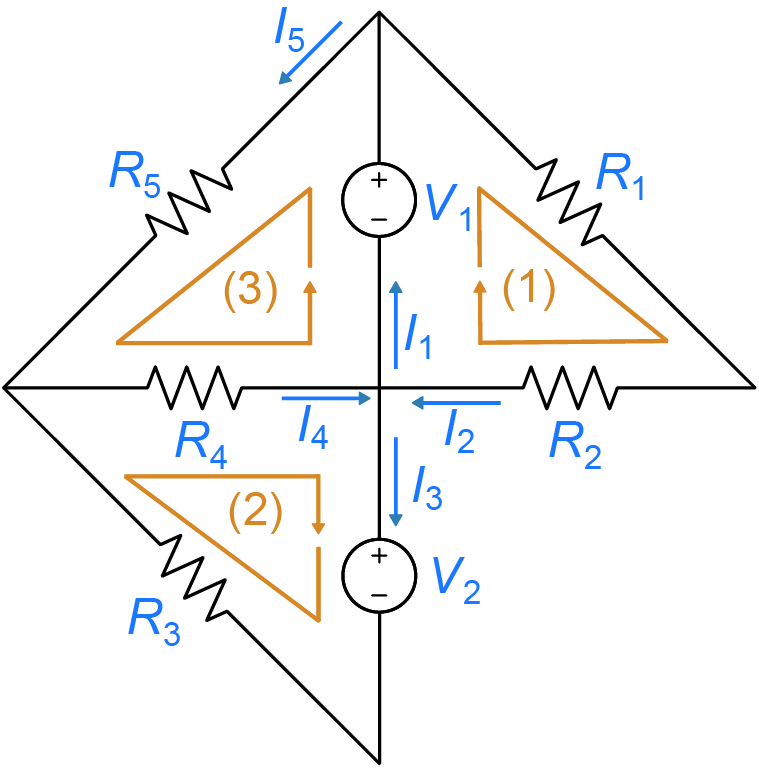

*In this diagram, three closed loops of the circuit are labeled (1), (2), and (3). The distinct currents in the circuit are also labeled.*

Applying **Kirchhoff's current law** to the central node yields:

    
$$I_2 + I_4 = I_1 + I_3$$


Applying **Kirchhoff's voltage law **to the three loops adds three additional equations:

    
$$\begin{array}{rl} 
\ V_1 - I_2 R_1 - I_2 R_2  &= 0
\\
- V_2 - I_3 R_3 - I_4 R_4  &= 0
\\
\ V_1 - I_5 R_5 - I_4 R_4  &= 0
\end{array}$$


At this point, you have 5 unknown currents but only four equations. To complete the representation, another application of Kirchhoff's current law is required. For the top node:

    
$$I_1 = I_2 + I_5$$


Note that there are additional loops and nodes to which you can apply Kirchhoff's law – but all of them will yield redundant conditions.

**Derivation of the matrix form of the equations**

To write these equations in matrix form $\mathbf{AI} = \mathbf{b}$, define the solution vector 

    
$$\mathbf{I} = \left( \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right)$$


Moving all variable terms to the LHS and constant terms to the RHS implies:

     $\begin{array}{rl} 
\ I_2 R_1 + I_2 R_2  &= V_1
\\
I_3 R_3 + I_4 R_4  &=  -V_2
\\
I_5 R_5  + I_4 R_4  &= V_1  
\\
I_1 - I_2 + I_3 - I_4 &= 0
\\
I_1 - I_2 - I_5 &= 0
\end{array}$        (1)

** Exercise**.

(a) Rewrite the system (1) in matrix form $\mathbf{AI} = \mathbf{b}$ by determining the form of $\mathbf{A}$ and $\mathbf{b}$.

showSolution = false;
if(showSolution)
    showCircuitMatrices
end

(b) Compute the matrix product $\mathbf{AI}$ to verify that the matrix form matches the original system (1).

**Solutions to the matrix system**

**Specific solution. **

** Exercise**. Suppose that the resistors and voltage sources have values:

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 100 \ \Omega
\\
R_3 = 10 \ \Omega
\\
R_4 = 1 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 1.5 \ \text{V}
\end{array}$$


What are the currents through the circuit? Store the vector of currents in variable `I`. 

**Hints: **

- Solve for the current by defining the numeric matrix `A`, the RHS vector `b`, and then applying the backslash operator (\). 

- Resistance is often given in terms of $\Omega$, $k\Omega$, and $M\Omega$.

% Write your code here


 This checks your solution against the expected answer

try
    currentCheck1(I)
catch ME
    warning("Check failed because: " + ME.message)
end

**General solution.** 

** Exercise**. Use symbolic math to find currents through this circuit for arbitrary resistances and voltages. 

Define symbolic variables for the resistances and voltages (e.g.,` syms R_1 V_1 `).

(a) Solve for the current by defining a symbolic matrix `A` and RHS vector `b` in terms of the symbolic variables defined above. Then, apply the backslash operator (\) to solve for the currents. Store the currents in `Isym`.

(b) Evaluate the general symbolic solution computed in (a) for the specific solution with parameters:

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 200 \ \Omega
\\
R_3 = 10 \ k \Omega
\\
R_4 = 2 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 12 \ \text{V}
\end{array}$$


Store the result in `Ispec`.

**Hint:** You can evaluate the symbolic solution for specific values of the variables in MATLAB. To do so, use [`matlabFunction`](https://www.mathworks.com/help/symbolic/matlabfunction.html) to generate a MATLAB function handle and then evaluate it with the specific values of the parameters. This process is illustrated in an example below.

This code creates a symbolic function `g`, which is subsequently converted to a MATLAB function handle `gfunc`, which is then evaluated at $x = 2$ and $y = 3$.

% Create a MATLAB function from the symbolic expression Isym

% Evaluate the function for the specified values, store the result in Ispec


This checks your solution against the expected answer

try
    currentCheck2(Ispec)
catch ME
    warning("Check failed because: " + ME.message)
end

Supporting functions for the linear circuits application

function showCircuitMatrices 
    syms R_1 R_2 R_3 R_4 R_5 V_1 V_2
    A = [0 R_1+R_2   0   0   0; 
         0       0 R_3 R_4   0;
         0       0  0  R_4 R_5;
         1      -1  1   -1   0;
         1      -1  0    0  -1]
    b = [V_1; -V_2; V_1; 0; 0]
end

function currentCheck1(Iuser)
    A = [0 110  0   0   0; 
         0   0 10 1e3   0;
         0   0  0 1e3 330;
         1  -1  1  -1   0;
         1  -1  0   0  -1];
    b = [1.5 -1.5 1.5 0 0]';
    I = A\b;
    isEqualCheck(Iuser,I); 
end

function currentCheck2(Iuser)
    syms R_1 R_2 R_3 R_4 R_5 V_1 V_2
    A = [0 R_1+R_2   0   0   0; 
         0       0 R_3 R_4   0;
         0       0  0  R_4 R_5;
         1      -1  1   -1   0;
         1      -1  0    0  -1];
    b = [V_1; -V_2; V_1; 0; 0];
    Isym = A\b;
    Ifunc = matlabFunction(Isym)
    Ispec = Ifunc(10,200,10e3,2e3,330,1.5,12);
    isEqualCheck(Iuser,Ispec); 
end

function correct = isEqualCheck(userSubmission, correctAnswer)
    correct = true;
    if( isequal(userSubmission, correctAnswer) && (class(correctAnswer)=="sym") )
        disp("Correct!")
    elseif ( all( abs(userSubmission - correctAnswer) < 1e-5 ) )
        disp("Correct!")     
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

Suppress unused suggestions

%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*DEFNU> 